%----------------------- barker code sidelobe 감쇠 표 정리 ------------------------------
Code_Length = [1 2 3 4 5 7 11 13]';

psl = zeros(length(Code_Length), 1);
ac = dsp.Autocorrelator;    % 내장함수
barker = comm.BarkerCode;   % 내장함수

for i = 1 : length(Code_Length)
    spf = Code_Length(i); 
    barker.Length = Code_Length(i);
    barker.SamplesPerFrame = spf;    
    seq = barker();
    
    sll_dB = 20 * log10(abs(ac(seq)));
    psl(i) = -(max(sll_dB));  
    release(barker);
    release(ac);
end

Sidelobe_dB = psl;
T = table(Code_Length, Sidelobe_dB) % table로 나타냄

T = 8×2 table
    Code_Length    Sidelobe_dB
    ___________    ___________

         1                 0  
         2           -6.0206  
         3           -9.5424  
         4           -12.041  
         5           -13.979  
         7           -16.902  
        11           -20.828  
        13           -22.279  



%----------------------------------------------------------------------------
%Bn -> matched filter -> mf_signal -> transval filter, order N -> tf_signa

t = -10 : 0.1 : 10

t =   -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000


% tau_prime = 13
% N = 13
% delta_tau = tau_prime / N
% beta_k = 

% 13 delta_tau = tau'
ex_bakercode13 = [0 -1 0 -1 0 -1 0 -1 0 -1 0 -1 11 -1 0 -1 0 -1 0 -1 0 -1 0 -1 0]

ex_bakercode13 =      0    -1     0    -1     0    -1     0    -1     0    -1     0    -1    11    -1     0    -1     0    -1     0    -1     0    -1     0    -1     0


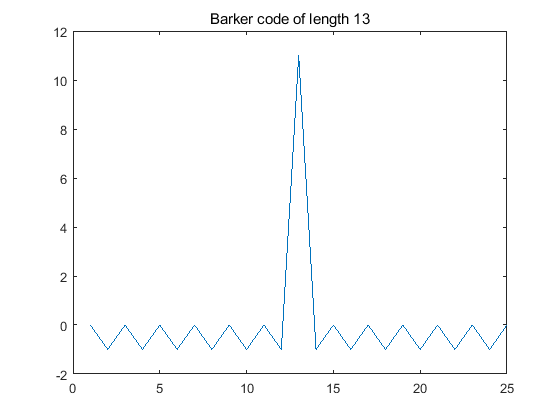

plot(ex_bakercode13)
title("Barker code of length 13")


%-------------------------------------------------------------------------------
% B11 = { + + + - - - + - - + - }
B11 = [1 1 1 0 0 0 1 0 0 1 0]

B11 =      1     1     1     0     0     0     1     0     0     1     0


% theta_11 : B11의 autocorrelation
theta_11 = [-1 0 -1 0 -1 0 -1 0 -1 0 11 0 -1 0 -1 0 -1 0 -1 0 -1]

theta_11 =     -1     0    -1     0    -1     0    -1     0    -1     0    11     0    -1     0    -1     0    -1     0    -1     0    -1


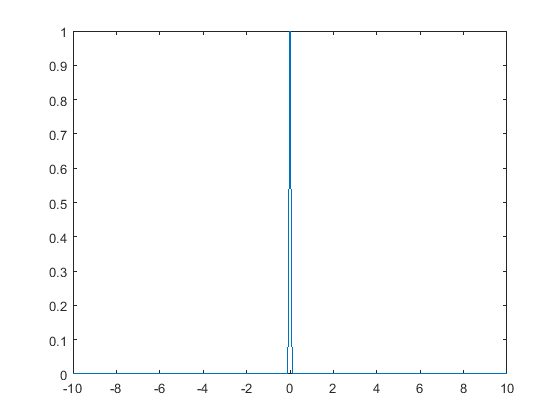


%---------------------------- impulse response h(t) ---------------------------
% impulse
impulse = t==0;
plot(t, impulse)


% 최종 h(t)
syms k N beta delta_tau
%ht = symsum(beta_k*impulse(t-2*k*delta_tau), k, -N, N)

% matched filter
beta_matrix = [11 -2 -2 -2 -2, -1 10 -2 -2 -1, -1 -2 10 -2 -1, ...
    -1 -2 -1 11 -1, -1 -1 -1 -1 11]

beta_matrix =     11    -2    -2    -2    -2    -1    10    -2    -2    -1    -1    -2    10    -2    -1    -1    -2    -1    11    -1    -1    -1    -1    -1    11



%X=[11 0 -1 0 -1]

X =     11     0    -1     0    -1


Y = beta_matrix .* X'

Y =    121   -22   -22   -22   -22   -11   110   -22   -22   -11   -11   -22   110   -22   -11   -11   -22   -11   121   -11   -11   -11   -11   -11   121
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   -11     2     2     2     2     1   -10     2     2     1     1     2   -10     2     1     1     2     1   -11     1     1     1     1     1   -11
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   -11     2     2     2     2     1   -10     2     2     1     1     2   -10     2     1     1     2     1   -11     1     1     1     1     1   -11


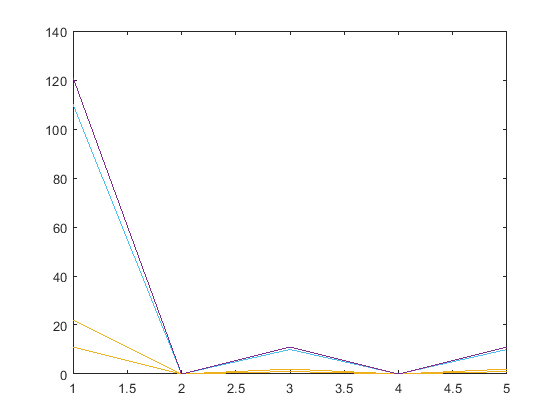

plot(abs(Y))

% transversal filter, order N